path = "E:\dataset";
dateFolders = dir(path);
dateFolders = dateFolders([dateFolders.isdir]);
subSize = 20;
rng(1)
    
numSeqs = 0;
    
for i = 3:length(dateFolders)
    dateName = dateFolders(i).name;
    datePath = fullfile(path,dateName);
    if ~isfile(fullfile(datePath,'calib_cam_to_cam.txt')), continue; end

    sequenceFolders = dir(datePath);
    sequenceFolders = sequenceFolders([sequenceFolders.isdir]);
    
    numSeqs = numSeqs + length(sequenceFolders) - 2;
end
    

subset.frameNum = subSize;
subset.numSeq   = numSeqs;
subset.paths    = strings(1,numSeqs);
subset.starts   = zeros(1,numSeqs);
subset.As       = zeros(3,numSeqs);

n = 1;

for i = 3:length(dateFolders)
    dateName = dateFolders(i).name;
    datePath = fullfile(path,dateName);
    if ~isfile(fullfile(datePath,'calib_cam_to_cam.txt')), continue; end

    sequenceFolders = dir(datePath);
    sequenceFolders = sequenceFolders([sequenceFolders.isdir]);

    for j = 3:length(sequenceFolders)
        sequenceName = sequenceFolders(j).name;
        sequencePath = fullfile(datePath, sequenceName);
        
        fid = fopen(fullfile(sequencePath,'haze','props.json'));
        if fid<0
            fprintf("props.json not found for sequence %s. Skipping\n",sequenceName)
            continue;
        end
        rawJSON = fread(fid);
        str = char(rawJSON');
        fclose(fid);
        hazeProps = jsondecode(str);

        trueA = hazeProps.A;
        A = reshape(trueA, [1 1 3]);
        
        JPath = fullfile(sequencePath,'image_02','data');
        JSize = length(dir(JPath))-2;
        
        
        % Don't include first and last frame.
        start = randi(JSize-subSize-1);
        
        subset.paths(n) = sequencePath;
        subset.starts(n) = start;
        subset.As(:,n) = trueA;
        
        n = n + 1;

    end
end

alpha = optimizableVariable('alpha',[1,100],'Transform','log');
alpha2 = optimizableVariable('alpha2',[1,30],'Transform','log');
radius = optimizableVariable('radius',[3,120],'Type','integer');


vars = radius;
init = cell2table({15},'VariableNames',{'radius'});
lfg = @(a, b)(@(b)lossFunc('normal',b,a));
fun = lfg(subset);
optNorm = bayesopt(fun,vars,'IsObjectiveDeterministic',true,'InitialX',init,'MaxObjectiveEvaluations',100);%,'UseParallel',true);

vars = alpha;
init = cell2table({80},'VariableNames',{'alpha'});
lfg = @(a, b)(@(b)lossFunc('smooth',b,a));
fun = lfg(subset);
optSmooth = bayesopt(fun,vars,'IsObjectiveDeterministic',true,'InitialX',init,'MaxObjectiveEvaluations',100);%,'UseParallel',true);

vars = [alpha, radius];
init = cell2table({15,80},'VariableNames',{'radius','alpha'});
lfg = @(a, b)(@(b)lossFunc('smooth2',b,a));
fun = lfg(subset);
optSmooth2 = bayesopt(fun,vars,'IsObjectiveDeterministic',true,'InitialX',init,'MaxObjectiveEvaluations',100);%,'UseParallel',true);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).
|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        alpha |       radius |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.033627 |      44.196 |    0.033627 |    0.033627 |           15 |           80 |
|    2 | Accept |    0.058835 |      9.4724 |    0.033627 |    0.033627 |       72.075 |          112 |
|    3 | Accept |    0.058585 |      7.8438 |    0.033627 |    0.033627 |       55.226 |          115 |
|    4 | Best   |      0.0286 |      8.1036 |      0.0286 |      0.0286 |       7.7184 |           39 |
|    5 | Accept |    0.063299 |      8.1364 |     

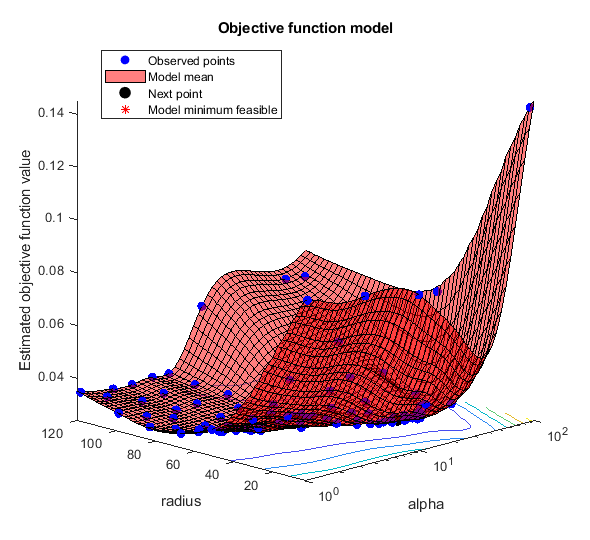

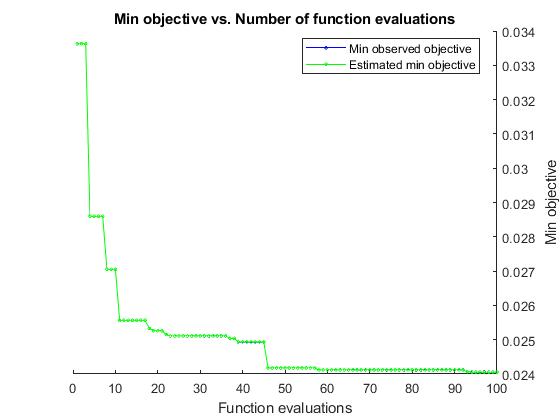


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 100 reached.
Total function evaluations: 100
Total elapsed time: 912.7483 seconds
Total objective function evaluation time: 844.9651

Best observed feasible point:
    alpha     radius
    ______    ______

    37.017      36  

Observed objective function value = 0.024057
Estimated objective function value = 0.024054
Function evaluation time = 8.6604

Best estimated feasible point (according to models):
    alpha     radius
    ______    ______

    37.017      36  

Estimated objective function value = 0.024054
Estimated function evaluation time = 8.2678



vars = [alpha, radius];
init = cell2table({15,80},'VariableNames',{'radius','alpha'});
lfg = @(a, b)(@(b)lossFunc('smooth3',b,a));
fun = lfg(subset);
optSmooth3 = bayesopt(fun,vars,'IsObjectiveDeterministic',true,'InitialX',init,'MaxObjectiveEvaluations',100);%,'UseParallel',true);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        alpha |       alpha2 |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.031339 |      10.455 |    0.031339 |    0.031339 |           15 |           10 |
|    2 | Accept |    0.094564 |      9.3109 |    0.031339 |    0.031339 |       7.4216 |       2.2665 |
|    3 | Best   |    0.027279 |      9.8244 |    0.027279 |    0.027279 |        44.14 |       9.9621 |
|    4 | Accept |    0.086662 |      9.6147 |    0.027279 |    0.027279 |       7.9603 |         3.12 |
|    5 | Best   |    0.025016 |      9.3024 |    0.025016 |    0.025016 |       99.761 |       24.771 |
|    6 | Accept |    0.026418 |      9.2213 |    0.025016 |    0

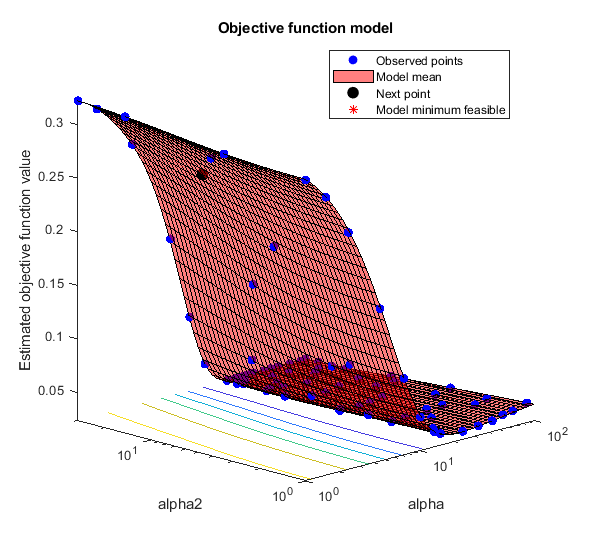

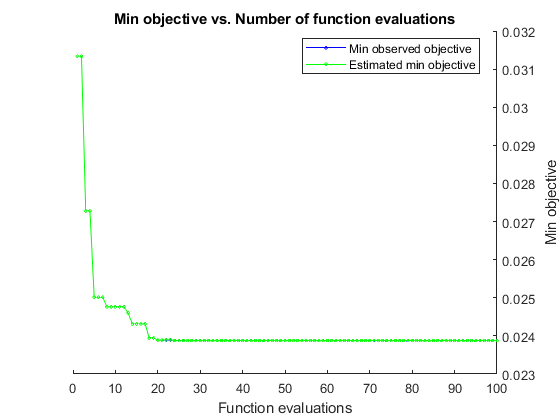


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 100 reached.
Total function evaluations: 100
Total elapsed time: 993.7698 seconds
Total objective function evaluation time: 926.7269

Best observed feasible point:
    alpha     alpha2
    ______    ______

    25.509    29.966

Observed objective function value = 0.023877
Estimated objective function value = 0.02388
Function evaluation time = 9.7798

Best estimated feasible point (according to models):
    alpha    alpha2
    _____    ______

    24.87    29.983

Estimated objective function value = 0.023877
Estimated function evaluation time = 9.2631



vars = [alpha, alpha2];
init = cell2table({15,10},'VariableNames',{'alpha','alpha2'});
lfg = @(a, b)(@(b)lossFunc('smooth4',b,a));
fun = lfg(subset);
optSmooth4 = bayesopt(fun,vars,'IsObjectiveDeterministic',true,'InitialX',init,'MaxObjectiveEvaluations',100);%,'UseParallel',true);

function loss = lossFunc(method, vars, subset)

    if method=="normal"
        radius = vars.radius;
        alpha2 = [];
        alpha = [];
    elseif method=="smooth"
        radius = [];
        alpha = vars.alpha;
        alpha2 = [];
    elseif method=="smooth4"
        radius = [];
        alpha = vars.alpha;
        alpha2 = vars.alpha2;
    else
        radius = vars.radius;
        alpha = vars.alpha;
        alpha2 = [];
    end
    
    
    frameNum    = subset.frameNum;
    seqPaths    = subset.paths;
    seqStarts   = subset.starts;
    seqAs       = subset.As;
 
    seqERRS   = zeros(1,subset.numSeq);
    
    parfor i = 1:length(seqPaths)
        
        sequencePath = seqPaths(i);
        IPath = fullfile(sequencePath,'haze','image');
        A = reshape(seqAs(:,i), [1 3]);

        errs              = zeros(1,frameNum);
        
        for frameID = 0:frameNum-1
            
            framePath = num2str(frameID+seqStarts(i),'%010.f')+".png";
            
            indexA = frameID + 1;

            I = imread(fullfile(IPath,framePath));
            I = im2double(I);  
            
            
            if method=="smooth"
                pA = atmsmooth(I,alpha);
            elseif method=="smooth2"
                pA = atmsmooth2(I,alpha,radius);
            elseif method=="smooth3"
                pA = atmsmooth3(I,alpha,radius);
            elseif method=="smooth4"
                pA = atmsmooth4(I,alpha,alpha2);
            else
                pA = atm(I,radius);
            end
            
            errs(indexA) = mean(abs(A-pA));
        end
        
        seqERRS(i) = mean(errs);
    end
    
    loss = mean(seqERRS);
end


function A = atm(img, radius)
    [m, n, ~] = size(img);

    darkChannel = min(img,[],3);
    se = strel('square',radius);
    darkChannel = imerode(darkChannel,se);

    nPixels = m * n;

    nSearchPixels = floor(nPixels * 0.01);
    darkVec = reshape(darkChannel, nPixels, 1);
    imageVec = reshape(img, nPixels, 3);
    [~,ind] = maxk(darkVec, nSearchPixels);
    A = mean(imageVec(ind,:),1);
end

function A = atmsmooth(img,alpha)

    flat = reshape(img, [], 3);
    eimg = exp(alpha.*flat);
    
    eimg = eimg./sum(eimg,1);
    A = sum(flat.*eimg,1);
end


function A = atmsmooth2(img,alpha,radius)
    [m, n, ~] = size(img);

    darkChannel = min(img,[],3);
    se = strel('square',radius);
    darkChannel = imerode(darkChannel,se);

    nPixels = m * n;
    
    darkVec = reshape(darkChannel, nPixels, 1);
    imageVec = reshape(img, nPixels, 3);
    
    eimg = exp(alpha.*darkVec);
    eimg = eimg./sum(eimg,1);

    A = sum(imageVec.*eimg,1);
end

function A = atmsmooth3(img,alpha,radius)
    [m, n, ~] = size(img);

    darkChannel = min(img,[],3);
    
    expD = exp(-alpha.*darkChannel);

    denom = windowSumFilter(expD,radius);
    darkChannel = windowSumFilter(expD.*darkChannel,radius)./denom;

    nPixels = m * n;
    
    nSearchPixels = floor(nPixels * 0.01);
    darkVec = reshape(darkChannel, nPixels, 1);
    imageVec = reshape(img, nPixels, 3);
    [~,ind] = maxk(darkVec, nSearchPixels);
    A = mean(imageVec(ind,:),1);
end

function A = atmsmooth4(img,alpha1,alpha2)
    [m, n, ~] = size(img);

    darkChannel = min(img,[],3);
    
    expD = exp(-alpha2.*darkChannel);

    denom = windowSumFilter(expD,50);
    darkChannel = windowSumFilter(expD.*darkChannel,50)./denom;

    nPixels = m * n;
    
    darkVec = reshape(darkChannel, nPixels, 1);
    imageVec = reshape(img, nPixels, 3);
    
    eimg = exp(alpha1.*darkVec);
    eimg = eimg./sum(eimg,1);

    A = sum(imageVec.*eimg,1);
end


function sumImg = windowSumFilter(image, r)

    % sum_img(x, y) = = sum(sum(image(x-r:x+r, y-r:y+r)));

    [h, w] = size(image);
    sumImg = zeros(size(image));

    % Y axis
    im_cum = cumsum(image, 1);

    sumImg(1:r+1, :) = im_cum(1+r:2*r+1, :);
    sumImg(r+2:h-r, :) = im_cum(2*r+2:h, :) - im_cum(1:h-2*r-1, :);
    sumImg(h-r+1:h, :) = repmat(im_cum(h, :), [r, 1]) - im_cum(h-2*r:h-r-1, :);

    % X axis
    im_cum = cumsum(sumImg, 2);

    sumImg(:, 1:r+1) = im_cum(:, 1+r:2*r+1);
    sumImg(:, r+2:w-r) = im_cum(:, 2*r+2:w) - im_cum(:, 1:w-2*r-1);
    sumImg(:, w-r+1:w) = repmat(im_cum(:, w), [1, r]) - im_cum(:, w-2*r:w-r-1);

end

